%NOTE 
%This code is not generic.

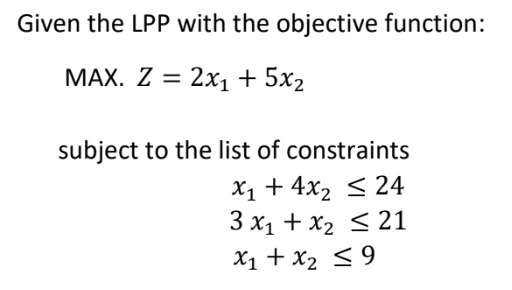

%Matrices are directly derived from the Question
%cost matrix
z = [2;5];

%Coefficient matrix
A = [1 4;3 1;1 1];

%b vector
b = [24;21;9];

%introducing slack variables
I = eye(size(A,1));

%we take slack vars as basic vars
Basic_vars = [3;4;5];            % 1 -> x1 ; 2 -> x2 ; 3 -> s1 ; 4 -> s2 ; 5 -> s3

%****************************** TABLE 1 ******************************%
%here all the constraint are having  less than inequality so coeff. of I will be +1 only
Table_1 = [A,I];
Z_row = [transpose(-z) 0 0 0 0];

%Append the Zj - Cj row in the table
Table_1 = [Table_1,b];
Table_1 = [Z_row;Table_1];

%now we have to decide the exiting variable and the entering variable

%------------------ENTERING------------------%
[min_ele,idx] = min(Z_row,[],'all');

%Checking whether the element is negative or not
if (min_ele >= 0)
    %the table is already the optimal table
    Table_1
    opti_ans = answer(Table_1,Basic_vars);
    Optimal_Value = opti_ans(1,1)
    x1 = opti_ans(2,1)
    x2 = opti_ans(3,1)
end

%find mrv of idx column
mrv = find_mrv(Table_1,b,idx);

%----------------Exiting-----------------------%
%finding the minimum MRV
[min_mrv,idx_mrv] = min(mrv,[],'all');

%the pivot row and pivot element
pivot_ele = Table_1(idx_mrv+1,idx);
pivot_row = idx_mrv + 1;

%updating the basic variables
Basic_vars(pivot_row - 1,1) = idx;


%****************************** TABLE 2 ******************************%

%Creating new table 
Table_2 = change_table(Table_1,pivot_ele,pivot_row,idx);

%Now doing the same procedure for to make table 3
[min_ele,idx] = min(Table_2(1),[],'all');

%Checking  whether the element is negative or not

if (min_ele >= 0)
    %the table is already the optimal table
    Table_1
    Table_2
    opti_ans = answer(Table_2,Basic_vars);
    Optimal_Value = opti_ans(1,1)
    x1 = opti_ans(2,1)
    x2 = opti_ans(3,1)
end
%finding the mrvs to find the exiting variable
mrv_2 = find_mrv(Table_2,b,idx);

[min_mrv,idx_mrv] = min(mrv_2,[],'all');

pivot_ele = Table_2(idx_mrv+1,idx);
pivot_row = idx_mrv+1;

%updating the basic variables
Basic_vars(pivot_row - 1,1) = idx;

%****************************** TABLE 3 ******************************%
%creating the third table
Table_3 = change_table(Table_2,pivot_ele,pivot_row,idx);

% Now doing the same procedure for to make table 4
[min_ele,idx] = min(Table_3(1),[],'all');

%Checking whether the element is negative or not
if (min_ele >= 0)
    %the table is already the optimal table
    Table_1
    Table_2
    Table_3
    opti_ans = answer(Table_3,Basic_vars);
    Optimal_Value = opti_ans(1,1)
    x1 = opti_ans(2,1)
    x2 = opti_ans(3,1)
end

Table_1 =     -2    -5     0     0     0     0
     1     4     1     0     0    24
     3     1     0     1     0    21
     1     1     0     0     1     9


Table_2 =    -0.7500         0    1.2500         0         0   30.0000
    0.2500    1.0000    0.2500         0         0    6.0000
    2.7500         0   -0.2500    1.0000         0   15.0000
    0.7500         0   -0.2500         0    1.0000    3.0000


Table_3 =          0         0    1.0000         0    1.0000   33.0000
         0    1.0000    0.3333         0   -0.3333    5.0000
         0         0    0.6667    1.0000   -3.6667    4.0000
    1.0000         0   -0.3333         0    1.3333    4.0000


Optimal_Value = 33

x1 = 4

x2 = 5

function output =  find_mrv(Table_1,b,idx)

    %taking i+1 as the first row is cost row(Zj - Cj)
    mrv = zeros([1 size(b,1)]);
    for i=1:size(b,1)
        mrv(i) = Table_1(i+1,6)/Table_1(i+1,idx);
    end

    output = transpose(mrv);
end

function new_table = change_table(table, pivot_ele,pivot_row,idx)

    %Changing Pivot row 
    for i=1:size(table,2)
         new_table(pivot_row,i) = table(pivot_row,i)/pivot_ele;
    end


    for i=1:size(table,1)
        if(i == pivot_row)
            continue
        else
            for j=1:size(table,2)
                new_table(i,j) = table(i,j) - table(i,idx)*new_table(pivot_row,j);
            end
        end
    end

end

function output = answer(table,basic_vars)

    %Find the indices of 1 and 2 in basic vars vector
    x1_idx = find(basic_vars==1) + 1;
    x2_idx = find(basic_vars==2) + 1;
    
    %Final Answer
    output(1,1) = table(1,size(table,2));
    output(2,1) = table(x1_idx ,size(table,2));
    output(3,1) = table(x2_idx ,size(table,2));
end